# Signal from Aluminum Disk at Varying Distances - Analysis

clear; clc;
addpath('../functions');

## Choose a center frequency

freq=3;

## Plot the signal at all distances

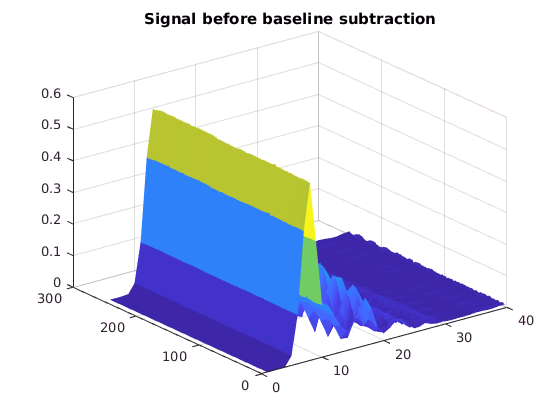

signal = []; 
for i=267:517
    data=obtain_data(i,'bb',freq);
    data=abs(data);
    signal=[signal;data];
end

figure;
surf(signal(:,1:40), 'LineStyle', 'None');
title('Signal before baseline subtraction');

## Plot the baseline

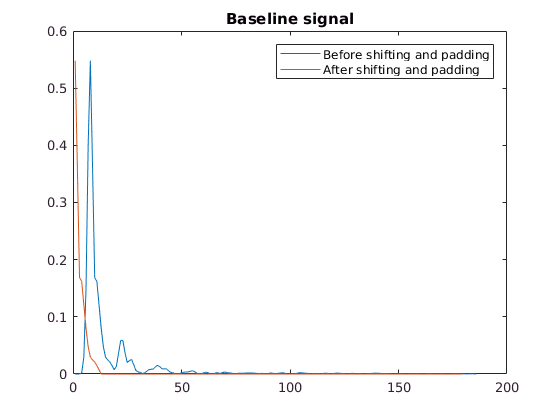

baseline=obtain_baseline('bb', freq);
figure;
plot(abs(baseline)); %Plot baseline with any shifting or padding
hold on;
[val_zero index_zero] = max(abs(baseline));
%Shift and pad baseline with zeros
baseline=baseline(index_zero:length(baseline));
baseline = [baseline(1:12) zeros(1,length(baseline)-12)];
plot(abs(baseline));
title('Baseline signal');
legend('Before shifting and padding','After shifting and padding')

## Plot the signal after baseline subtraction

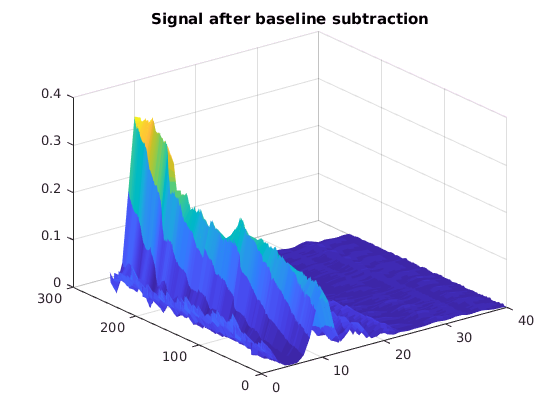

signal = []; 
peaks = [];
for i=267:517
    data=obtain_data(i,'bb',freq);
    data=data(index_zero:length(data));
    data=abs(data-baseline);
    peaks=[peaks max(data)];
    signal=[signal;data];
end

figure;
surf(signal(:,1:40), 'LineStyle', 'None');
title('Signal after baseline subtraction');

## Plot the peaks from the aluminum disk

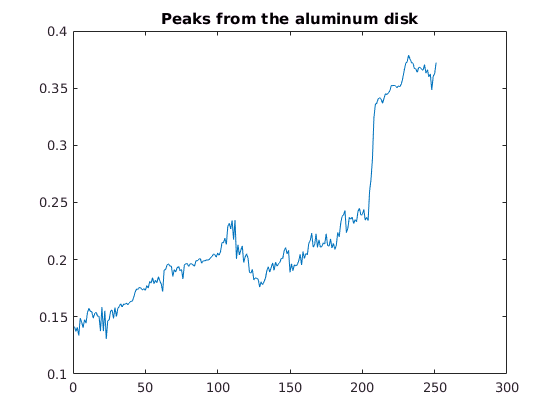

figure
plot(peaks);
title('Peaks from the aluminum disk');

## Isolate the pulse from the table

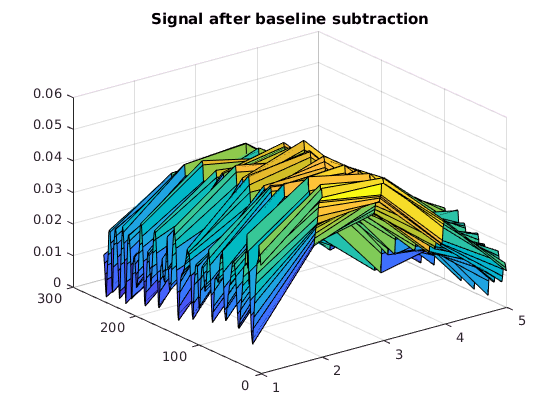

signal = []; 
peaks = [];
for i=267:517
    data=obtain_data(i,'bb',freq);
    data=data(index_zero:length(data));
    data=abs(data-baseline);
    data=data(14:18);
    peaks=[peaks max(data)];
    signal=[signal;data];
end

figure;
surf(signal);
title('Signal after baseline subtraction');

## Plot the peaks from the table 

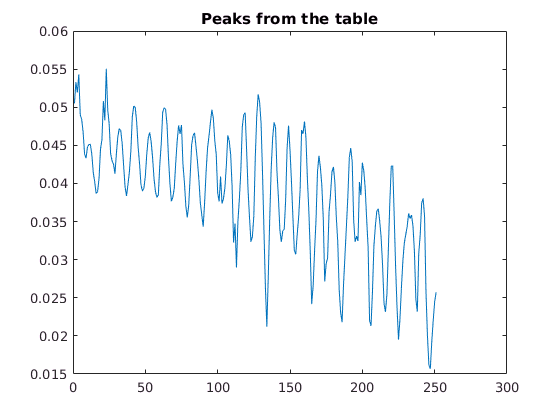

figure
plot(peaks);
title('Peaks from the table');

## Used the Matched filter with the input signal

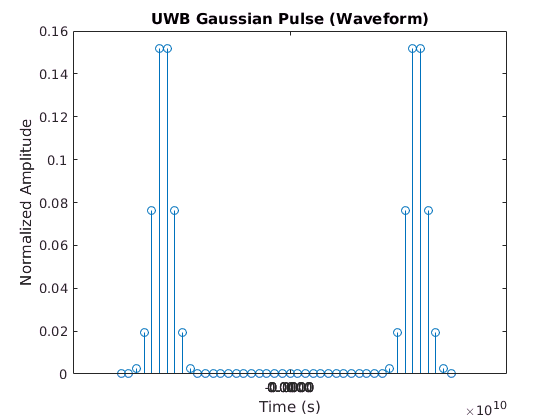

Fs = 23.328e9; % Sampling Frequnecy
Bw = 1.5e9;    % Bandwidth
Fc = 8.748e9;  % Center Frequency

[s_tx, S_tx, t, f] = uwb_wavelet(Fs, Bw, Fc);

for i = 267:517
    rf_data = obtain_data(i,'rf',freq);
    [dc_data(i,:),~] = match_and_downconvert(rf_data, s_tx, Fc);
end

[dc_data_baseline, lagDiff] = match_and_downconvert(obtain_baseline('rf', freq), s_tx, Fc);

for i = 267:517
    net_dc_data(i,:) = dc_data(i,:) - dc_data_baseline;
end

t_mf = linspace(0,200*2/Fs,200);
surf(t_mf,267:517, abs(net_dc_data(267:517,length(dc_data_baseline)/2+lagDiff/2:length(dc_data_baseline)/2+lagDiff/2+199)), 'LineStyle', 'None');

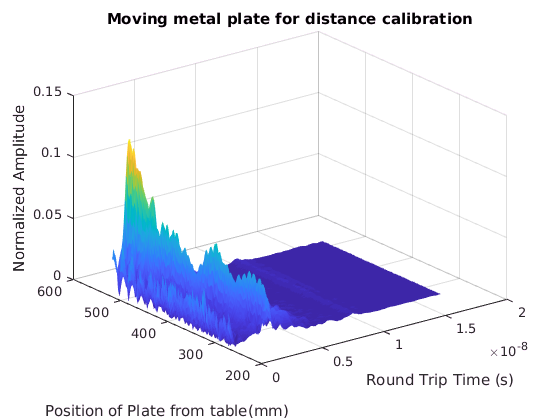

xlabel('Round Trip Time (s)');
ylabel('Position of Plate from table(mm)');
zlabel('Normalized Amplitude');
title('Moving metal plate for distance calibration');

for i = 267:517
   [~, dcdatamax(i)] = max(abs(net_dc_data(i,:)));
end
dcdatamax2 = (dcdatamax(267:517) - (length(dc_data_baseline)/2+lagDiff/2))*2/Fs;
dists = 750 - (267:517)

dists =    483   482   481   480   479   478   477   476   475   474   473   472   471   470   469   468   467   466   465   464   463   462   461   460   459   458   457   456   455   454   453   452   451   450   449   448   447   446   445   444   443   442   441   440   439   438   437   436   435   434


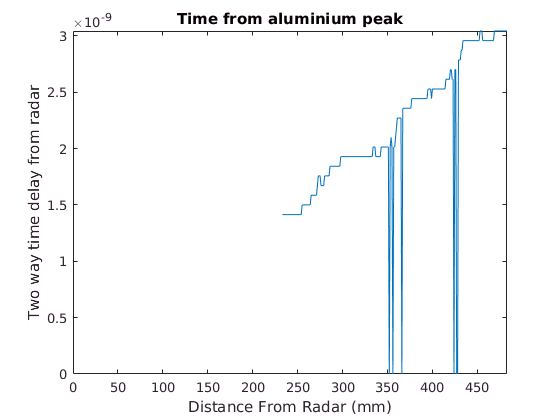

plot(dists, dcdatamax2);
axis([0 max(dists) 0 max(dcdatamax2)])
title('Time from aluminium peak');
ylabel('Two way time delay from radar');
xlabel('Distance From Radar (mm)');